data_dir = '/home/przemek/neurodata/ca_mecp2_culture/signal';
filepaths = listfiles(data_dir, '.*mat');

F_stats = [];
for i=1:numel(filepaths)
    filepath = filepaths{i};
    dat = load(filepath);
    Fcell = dat.dat.Fcell{1};
    FcellNeu = dat.dat.FcellNeu{1};
    fstat = FStats(dat.dat);
    F_stats = [F_stats filterFstat(fstat)];
end

nstats = numel(F_stats);

Set up conditions variable

conditions = arrayfun(@(x) x.condition, [F_stats.fileinfo], 'uniformoutput', false);
unique_conditions = unique(lower(conditions));
colours_array = hsv(numel(unique_conditions));
condition_index = containers.Map(unique_conditions, 1:numel(unique_conditions));
condtion_colours = containers.Map(unique_conditions, num2cell(colours_array,2));

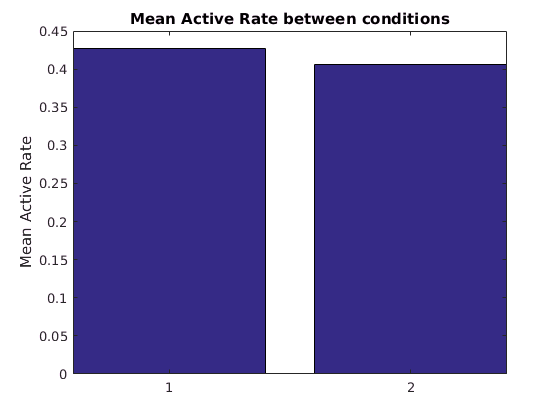

active_rate_means = arrayfun(@(x) mean(x.active_rate), F_stats);

wt_rates = active_rate_means(strcmp(lower(conditions),'mecp2wt'));
het_rates = active_rate_means(strcmp(lower(conditions),'mecp2het'));

bar([mean(wt_rates); mean(het_rates)]);
ylabel('Mean Active Rate');
title('Mean Active Rate between conditions');

sprintf('WT: mean %.2f std: %.2f', mean(wt_rates), std(wt_rates))

ans = WT: mean 0.43 std: 0.02

sprintf('Het: mean %.2f std: %.2f', mean(het_rates), std(het_rates))

ans = Het: mean 0.41 std: 0.03

all_ipis = cell(nstats, 1);
for findex=1:nstats
    F_stat = F_stats(findex);
    peaks = F_stat.peaks;
    ncells = numel(peaks);
    ipis = cell(ncells,1);
    for i=1:ncells
        end_indecies = [peaks{i}.end_index];
        start_indecies = [peaks{i}.start_index];
        intervals = bsxfun(@minus,...
                           start_indecies(2:end),...
                           end_indecies(1:end-1));
        ipis{i} = intervals';
    end
    
    F_stat.ipi = ipis;
    all_ipis{findex} = ipis;
    
end


Plot peaks rise stats

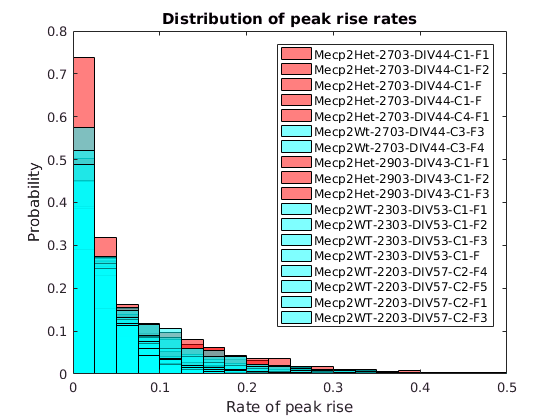

increase_rates = cell(numel(unique_conditions),1);
for i=1:numel(unique_conditions)
    increase_rates{i} = [];
end

fstats_legend = cell(nstats,1);
figure;
for findex=1:nstats
    F_stat = F_stats(findex);
    peaks = cell2mat(F_stat.peaks);
    fstats_legend{findex} = get_recording_name(F_stat.fileinfo);
    condtition = lower(F_stat.fileinfo.condition);
    c_index = condition_index(condtition);
    increase_rates{c_index} = [increase_rates{c_index} [peaks.increase_rate]];
    histogram([peaks.increase_rate], 'facealpha', 0.5,...
              'Normalization','probability',...
              'BinWidth', 0.025,...
              'FaceColor',condtion_colours(condtition),...
              'BinLimits', [0 0.5]);
    hold on;
end
hold off;
title('Distribution of peak rise rates');
xlabel('Rate of peak rise')
ylabel('Probability')
legend(fstats_legend);

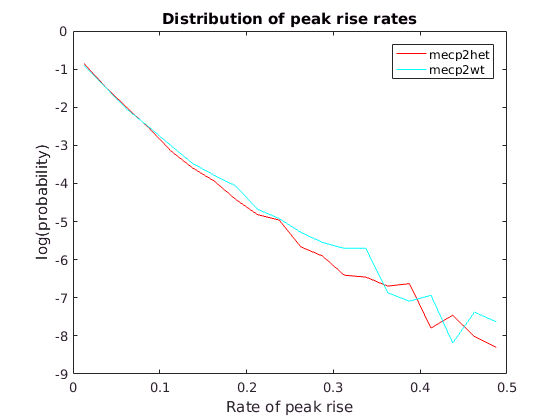

for i=1:numel(unique_conditions)
    colors = condtion_colours.values;
    bin_width = 0.025;
    [N,edges] = histcounts(increase_rates{i},....
          'Normalization','probability',...
          'BinWidth', bin_width,...
          'BinLimits', [0 0.5]);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, log(N), 'Color', colors{i});
    hold on;
end
hold off;
title('Distribution of peak rise rates');
xlabel('Rate of peak rise')
xlim([0 0.5])
ylabel('log(probability)')
legend(unique_conditions);

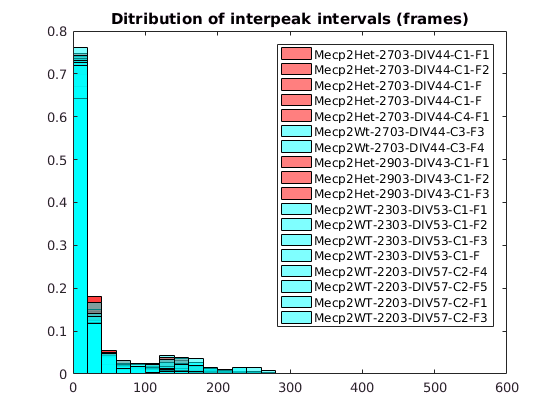

condition_ipis = cell(numel(unique_conditions),1);
for i=1:numel(unique_conditions)
    condition_ipis{i} = [];
end

fstats_legend = cell(nstats,1);
figure;
for findex=1:nstats
    F_stat = F_stats(findex);
    ipis = cell2mat(all_ipis{findex});
    condition = lower(F_stat.fileinfo.condition);
    c_index = condition_index(condition);
    condition_ipis{c_index} = [condition_ipis{c_index} ipis'];
    histogram(ipis, 'facealpha', 0.5,...
        'Normalization','probability',...
        'BinWidth', 20,...
        'FaceColor', condtion_colours(condition));
    fstats_legend{findex} = get_recording_name(F_stat.fileinfo);
    hold on;
end
hold off;
title('Ditribution of interpeak intervals (frames)');
legend(fstats_legend);

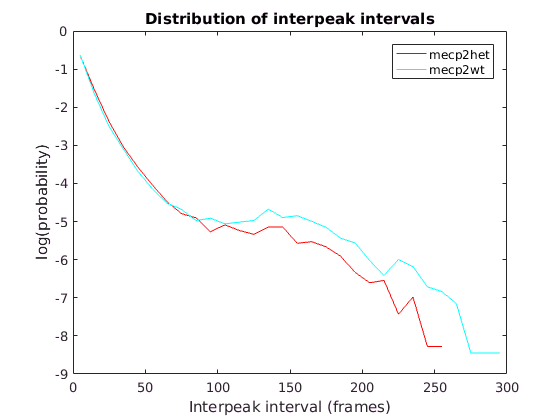


for i=1:numel(unique_conditions)
    colors = condtion_colours.values;
    bin_width = 10;
    [N,edges] = histcounts(condition_ipis{i},...
              'Normalization','probability',...
              'BinWidth', bin_width,...
              'BinLimits', [0 300]);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, log(N), 'Color', colors{i});
    hold on;
end
hold off;
title('Distribution of interpeak intervals');
xlabel('Interpeak interval (frames)')
ylabel('log(probability)')
legend(unique_conditions);

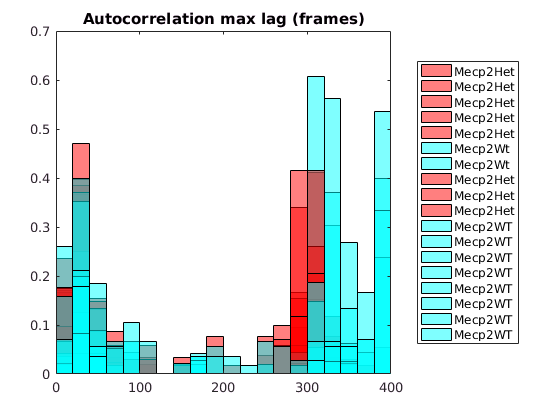

condition_acorrs = cell(numel(unique_conditions),1);
condition_lag_means = zeros(numel(F_stats),1);
for i=1:numel(unique_conditions)
    condition_acorrs{i} = [];
end

fstats_legend = cell(nstats,1);
figure;
for findex=1:nstats
    F_stat = F_stats(findex);
    c_index = condition_index(lower(F_stat.fileinfo.condition));
    condition_acorrs{c_index} = [condition_acorrs{c_index} F_stat.max_lag];
    
    condition_lag_means(findex) = mean(F_stat.max_lag(F_stat.max_lag > 100));
    histogram(F_stat.max_lag,'facealpha', 0.5,...
        'Normalization','probability',...
        'BinWidth',20,...
        'FaceColor', condtion_colours(lower(F_stat.fileinfo.condition)),...
        'DisplayName',F_stat.fileinfo.condition);
    hold on;
    finfo = F_stat.fileinfo;
    fstats_legend{findex} = get_recording_name(F_stat.fileinfo);
end
hold off;
title('Autocorrelation max lag (frames)');
legend('show', 'location', 'eastoutside');

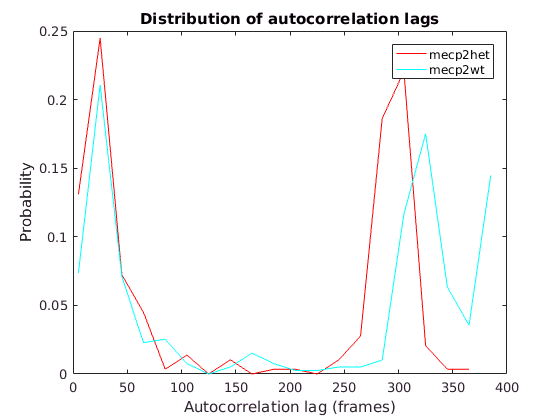


for i=1:numel(unique_conditions)
    colors = condtion_colours.values;
    [N,edges] = histcounts(condition_acorrs{i},...
              'Normalization','probability',...
              'BinWidth', 20);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, N, 'Color', colors{i});
    hold on;
end
hold off;
title('Distribution of autocorrelation lags');
xlabel('Autocorrelation lag (frames)')
ylabel('Probability')
legend(unique_conditions);

p = 3.5839e-04

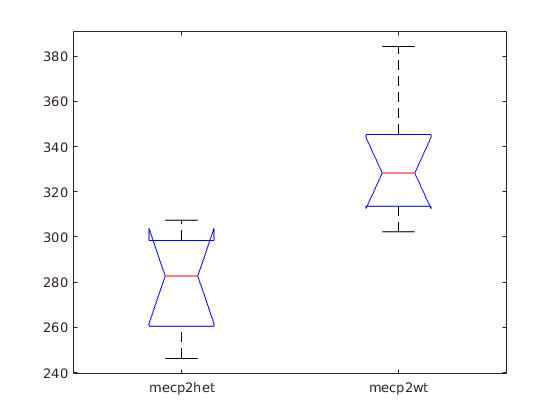

p=anova1(condition_lag_means, lower(conditions))

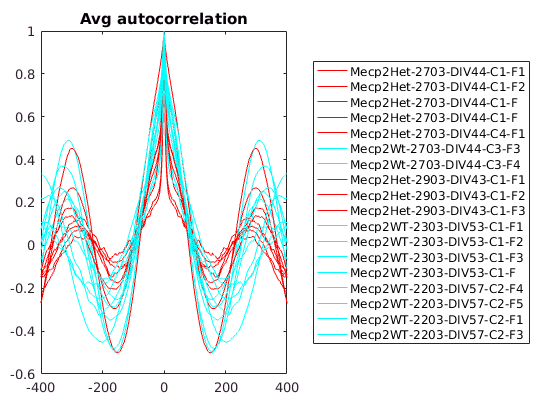

for findex=1:nstats
    F_stat = F_stats(findex);
    acorr = mean(F_stat.acorrs,1);
    max_lag = floor(length(acorr)/2);
    plot(-max_lag:max_lag, acorr,...
        'color', condtion_colours(lower(F_stat.fileinfo.condition)));
    hold on;
end
hold off;
title('Avg autocorrelation');
legend(fstats_legend, 'location', 'eastoutside');

function name = get_recording_name(finfo)
    name = [finfo.condition '-'...
            finfo.culture_date '-'...
            finfo.div '-'...
            'C' finfo.coverslip_id '-'...
            'F' finfo.fr_id...
           ];
end